# **Reinforced Concrete Frame Earthquake Analysis**

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;


ops.wipe();
% Create ModelBuilder (with two-dimensions and 3 DOF/node)
ops.model('basic', '-ndm', 2, '-ndf', 3);

% Create nodes
% ------------

% Set parameters for overall model geometry
width = 360.0;
height = 144.0;

% Create nodes
%    tag, X, Y
ops.node(1, 0.0, 0.0);
ops.node(2, width, 0.0);
ops.node(3, 0.0, height);
ops.node(4, width, height);

% Fix supports at base of columns
%   tag, DX, DY, RZ
ops.fix(1, 1, 1, 1);
ops.fix(2, 1, 1, 1);

% Define materials for nonlinear columns
% ------------------------------------------
% CONCRETE                   tag  f'c    ec0    f'cu   ecu
% Core concrete (confined)
ops.uniaxialMaterial('Concrete01', 1, -6.0, -0.004, -5.0, -0.014);

% Cover concrete (unconfined)
ops.uniaxialMaterial('Concrete01', 2, -5.0, -0.002, 0.0, -0.006);

% STEEL
% Reinforcing steel
fy = 60.0;      % Yield stress
E  = 30000.0;   % Young's modulus

%                         tag  fy E0    b
ops.uniaxialMaterial('Steel01', 3, fy, E, 0.01);

% Define cross-section for nonlinear columns
% ------------------------------------------

% some parameters
colWidth = 15;
colDepth = 24;

cover = 1.5;
As = 0.60;  % area of no. 7 bars

% some variables derived from the parameters
y1 = colDepth / 2.0;
z1 = colWidth / 2.0;

ops.section('Fiber', 1);

% Create the concrete core fibers
ops.patch('rect', 1, 10, 1, cover - y1, cover - z1, y1 - cover, z1 - cover);

% Create the concrete cover fibers (top, bottom, left, right)
ops.patch('rect', 2, 10, 1, -y1, z1 - cover, y1, z1);
ops.patch('rect', 2, 10, 1, -y1, -z1, y1, cover - z1);
ops.patch('rect', 2, 2, 1, -y1, cover - z1, cover - y1, z1 - cover);
ops.patch('rect', 2, 2, 1, y1 - cover, cover - z1, y1, z1 - cover);

% Create the reinforcing fibers (left, middle, right)
ops.layer('straight', 3, 3, As, y1 - cover, z1 - cover, y1 - cover, cover - z1);
ops.layer('straight', 3, 2, As, 0.0, z1 - cover, 0.0, cover - z1);
ops.layer('straight', 3, 3, As, cover - y1, z1 - cover, cover - y1, cover - z1);

% Define column elements
% ----------------------

% Geometry of column elements
ops.geomTransf('PDelta', 1);

% Number of integration points along length of element
np = 5;

% Lobatto integration
ops.beamIntegration('Lobatto', 1, 1, np);

% Create the columns using Beam-column elements
%               type              tag ndI ndJ transfTag integrationTag
eleType = 'forceBeamColumn';
ops.element(eleType, 1, 1, 3, 1, 1);
ops.element(eleType, 2, 2, 4, 1, 1);

% Define beam element
% -------------------

% Geometry of beam element
ops.geomTransf('Linear', 2);

% Create the beam element
%                          tag, ndI, ndJ, A,     E,     Iz,    transfTag
ops.element('elasticBeamColumn', 3, 3, 4, 360.0, 4030.0, 8640.0, 2);

% Define gravity loads
% --------------------

% a parameter for the axial load
P = 180.0;  % 10% of axial capacity of columns

% Create a Plain load pattern with a Linear TimeSeries
ops.timeSeries('Linear', 1);
ops.pattern('Plain', 1, 1);

% Create nodal loads at nodes 3 & 4
%    nd  FX,  FY, MZ
ops.load(3, 0.0, -P, 0.0);
ops.load(4, 0.0, -P, 0.0);

[OpenSeesMatlab] Model summary
  Nodes: 4
  Beam elements: 3


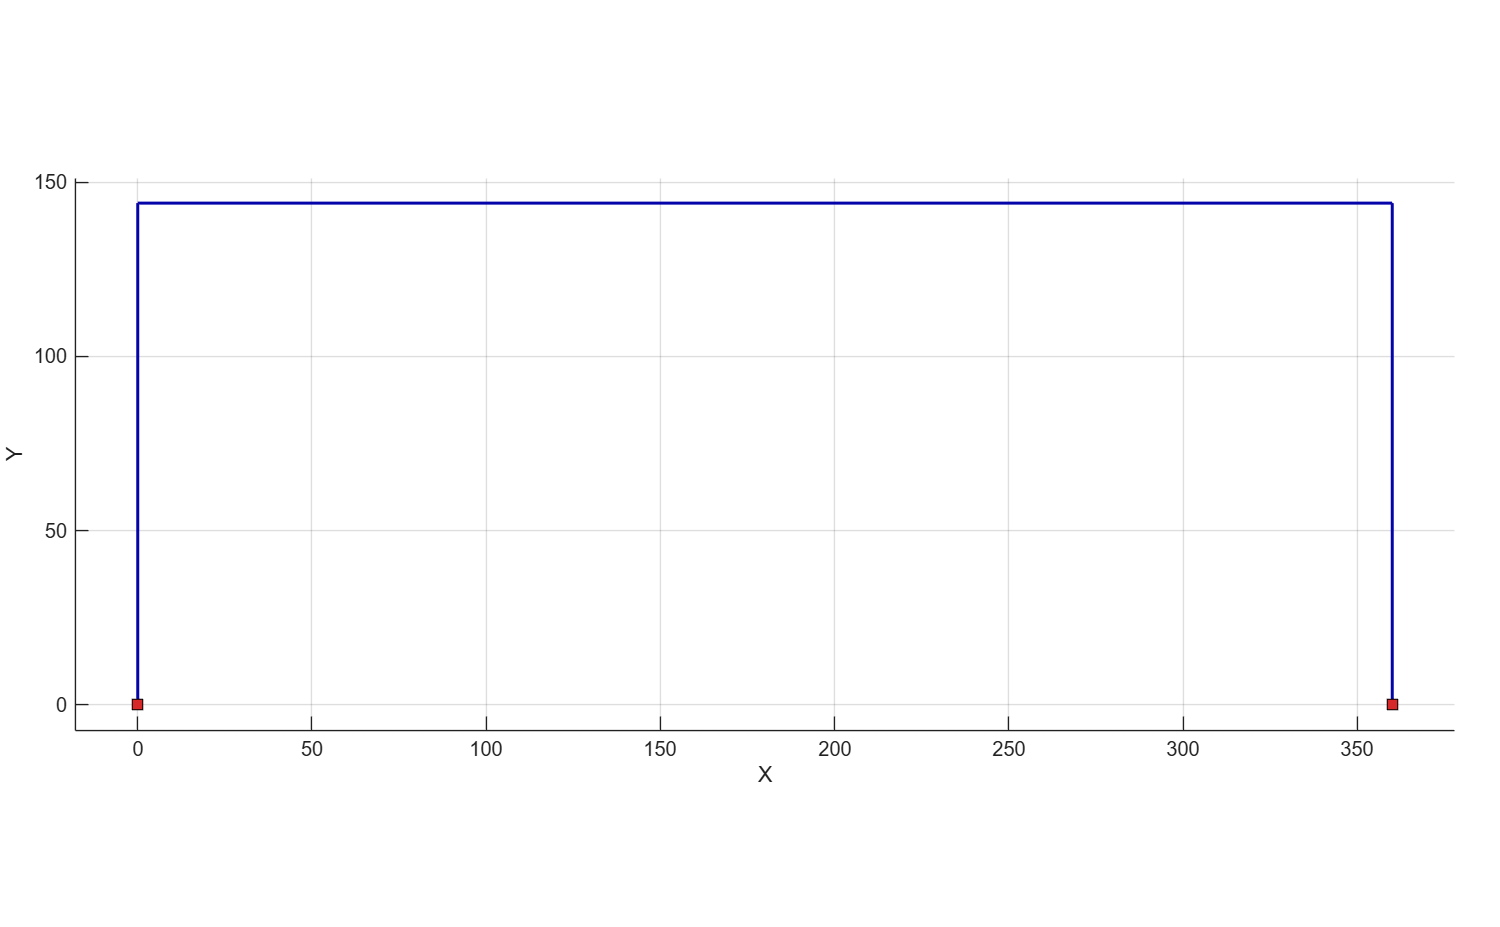

figure;
paras = opsMAT.vis.defaultPlotModelOptions();
paras.loads.showNodal = true;
paras.loads.scale = 5e-4;
opsMAT.vis.plotModel(opts=paras);


% ------------------------------
% End of model generation
% ------------------------------

% ------------------------------
% Start of analysis generation
% ------------------------------

% Create the system of equation, a sparse solver with partial pivoting
ops.system('BandGeneral');

% Create the constraint handler, the transformation method
ops.constraints('Transformation');

% Create the DOF numberer, the reverse Cuthill-McKee algorithm
ops.numberer('RCM');

% Create the convergence test
ops.test('NormDispIncr', 1.0e-12, 10, 1);

% Create the solution algorithm, a Newton-Raphson algorithm
ops.algorithm('Newton');

% Create the integration scheme, the LoadControl scheme using steps of 0.1
ops.integrator('LoadControl', 0.1);

% Create the analysis object
ops.analysis('Static');

% ------------------------------
% End of analysis generation
% ------------------------------

% ------------------------------
% Finally perform the analysis
% ------------------------------

% perform the gravity load analysis, requires 10 steps to reach the load level
ops.analyze(10);

[OpenSees] CTestNormDispIncr::test() - iteration: 1 current Norm: 0.00254558 (max: 1e-12, Norm R: 0.0507128)
[OpenSees] CTestNormDispIncr::test() - iteration: 2 current Norm: 5.09157e-06 (max: 1e-12, Norm R: 2.02883e-07)
[OpenSees] CTestNormDispIncr::test() - iteration: 3 current Norm: 2.03696e-11 (max: 1e-12, Norm R: 1.07973e-14)
[OpenSees] CTestNormDispIncr::test() - iteration: 4 current Norm: 1.03995e-18 (max: 1e-12, Norm R: 1.02195e-14)

[OpenSees] CTestNormDispIncr::test() - iteration: 1 current Norm: 0.00255579 (max: 1e-12, Norm R: 0.0511202)
[OpenSees] CTestNormDispIncr::test() - iteration: 2 current Norm: 5.15321e-06 (max: 1e-12, Norm R: 2.07825e-07)
[OpenSees] CTestNormDispIncr::test() - iteration: 3 current Norm: 2.09501e-11 (max: 1e-12, Norm R: 2.64684e-14)
[OpenSees] CTestNormDispIncr::test() - iteration: 4 current Norm: 2.306e-18 (max: 1e-12, Norm R: 2.19741e-14)

[OpenSees] CTestNormDispIncr::test() - iteration: 1 current Norm: 0.00256612 (max: 1e-12, Norm R: 0.0515341)
[


% Get nodal vertical displacements
u3 = ops.nodeDisp(3, 2);
u4 = ops.nodeDisp(4, 2);


if abs(u3 + 0.0183736) < 1e-6 && abs(u4 + 0.0183736) < 1e-6
    disp('Passed!')
else
    disp('Failed!')
end

Passed!



% Set the gravity loads to be constant & reset the time in the domain
ops.loadConst('-time', 0.0);

% ----------------------------------------------------
% End of Model Generation & Initial Gravity Analysis
% ----------------------------------------------------

% Define nodal mass in terms of axial load on columns
g = 386.4;
m = P / g;

ops.mass(3, m, m, 0.0);
ops.mass(4, m, m, 0.0);

[elcentro.txt](../utils/elcentro.txt)

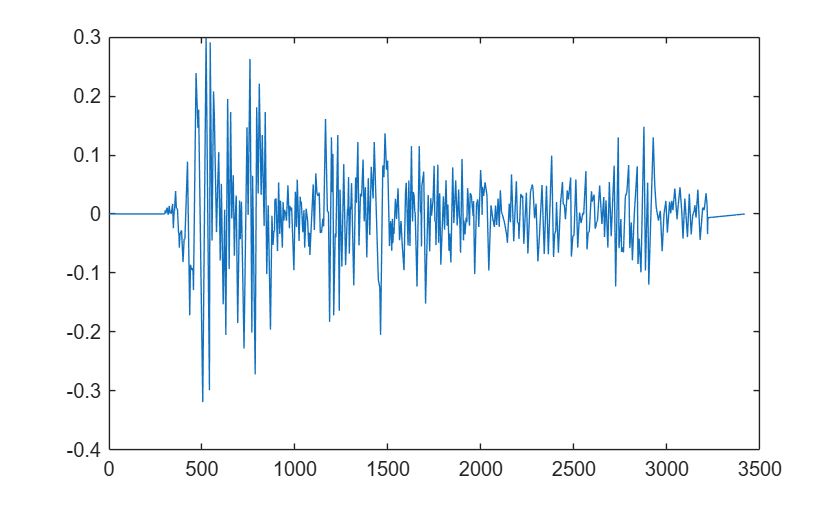


% Perform the conversion from SMD record to OpenSees record
% You need to provide this helper function in MATLAB yourself
dt = 0.01;
gm_data = load("utils/elcentro.txt") / 9.81;  % to g
gm_data = gm_data(:);
nPts = numel(gm_data);

figure;
plot(gm_data);


% Set time series to be passed to uniform excitation
ops.timeSeries('Path', 2, '-values', gm_data, '-dt', dt, '-factor', g);

% Create UniformExcitation load pattern
%                         tag dir
ops.pattern('UniformExcitation', 2, 1, '-accel', 2);

% set the rayleigh damping factors for nodes & elements
ops.rayleigh(0.0, 0.0, 0.0, 0.000625);

% Delete the old analysis and all its component objects
ops.wipeAnalysis();

% Create the system of equation, a banded general storage scheme
ops.system('BandGeneral');

% Create the constraint handler, a plain handler as homogeneous boundary
ops.constraints('Plain');

% Create the convergence test
ops.test('NormDispIncr', 1.0e-12, 10);

% Create the solution algorithm, a Newton-Raphson algorithm
ops.algorithm('Newton');

% Create the DOF numberer, the reverse Cuthill-McKee algorithm
ops.numberer('RCM');

% Create the integration scheme, the Newmark with alpha = 0.5 and beta = 0.25
ops.integrator('Newmark', 0.5, 0.25);

% Create the analysis object
ops.analysis('Transient');

% Perform an eigenvalue analysis
numEigen = 2;
eigenValues = ops.eigen(numEigen);
disp('eigen values at start of transient:')

eigen values at start of transient:


disp(eigenValues)

   1.0e+04 *

    0.0267    1.7504



% set some variables
tFinal = (nPts + 5000) * dt;
tCurrent = ops.getTime();
ok = 0;

time = tCurrent;
u3 = 0.0;

% Perform the transient analysis
while ok == 0 && tCurrent < tFinal

    ok = ops.analyze(1, 0.01);

    % if the analysis fails try initial tangent iteration
    if ok ~= 0
        disp('regular newton failed .. lets try an initail stiffness for this step')
        ops.test('NormDispIncr', 1.0e-12, 100, 0);
        ops.algorithm('ModifiedNewton', '-initial');
        ok = ops.analyze(1, 0.01);
        if ok == 0
            disp('that worked .. back to regular newton')
        end
        ops.test('NormDispIncr', 1.0e-12, 10);
        ops.algorithm('Newton');
    end

    tCurrent = ops.getTime();

    time(end+1,1) = tCurrent;
    u3(end+1,1) = ops.nodeDisp(3, 1);
end

% Perform an eigenvalue analysis
eigenValues = ops.eigen(numEigen);
disp('eigen values at end of transient:')

eigen values at end of transient:


disp(eigenValues)

   1.0e+04 *

    0.0165    1.7419



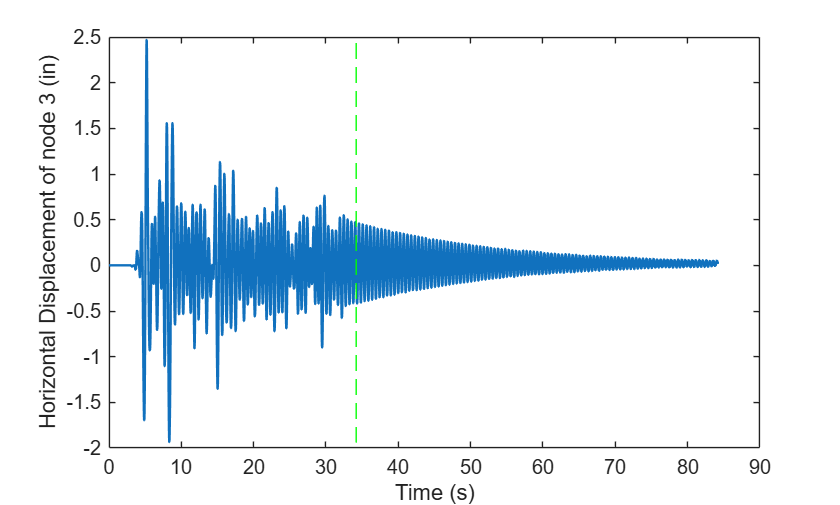

figure;
plot(time, u3, "LineWidth", 1.2);
hold on
plot([nPts*dt nPts*dt], [min(u3) max(u3)], "LineStyle", "--", "Color", "green");
ylabel('Horizontal Displacement of node 3 (in)');
xlabel('Time (s)');